clc;clear
N = 20

N = 20

r = 1.5

r = 1.5000


cities = [8.5, 6.2, 3.5, 5.1, 4.0, 0.8, 2.4, 1.2, 1.8, 2.4; 4.2, 0.5, 9.0, 9.4, 4.9, 4.9, 3.4, 9.0, 3.7, 1.1];
sequence = [10, 2, 1, 4, 3, 8, 6, 9, 7, 5]

sequence =     10     2     1     4     3     8     6     9     7     5


start = [0; 0];
corners = [0, 10, 10, 0; 0, 0, 10, 10];
% sequence = [1 2 3 4 5 6 7 8 9 10];
cities_x = [0 cities(1, sequence)]

cities_x =          0    2.4000    6.2000    8.5000    5.1000    3.5000    1.2000    0.8000    1.8000    2.4000    4.0000


cities_y = [0 cities(2, sequence)]

cities_y =          0    1.1000    0.5000    4.2000    9.4000    9.0000    9.0000    4.9000    3.7000    3.4000    4.9000


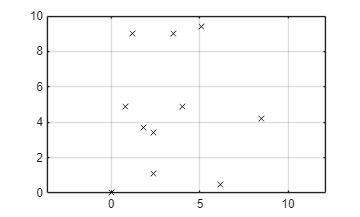


plot(cities_x, cities_y, "xk")
axis([0 10 0 10])
grid on
axis equal

setup functions for BPV4c

function H = Hamiltonian(s,r)

Index in position 2 exceeds array bounds. Index must not exceed 1.

gamma = -(r/2)*s(7);
if abs(gamma)>1
    gamma = sign(gamma);
end
a = -(r/2)*s(8);
if abs(a)>1
    a = sign(a);
end
H = 1 + (1/r)*(gamma^2 + a^2) + s(5)*s(4)*cos(s(3)) + s(6)*s(4)*sin(s(3)) + s(7)*gamma + s(8)*a;
end

function ds = ODEMain(t, s, times, r)
for ii = 1:numel(times)
    ds(ii*8-7:ii*8, 1) = ODEs(t, s(ii*8-7:ii*8), r)*times(ii);
end
end

function ds = ODEs(~, s, r)
% s(1) = x, s(2) = y, s(3) = theta, s(4) = v
% s(5) = lambda_x, s(6) = lambda_y, s(7) = lambda_theta, s(8) = lambda_v

gamma = -(r/2)*s(7);
if abs(gamma)>1
    gamma = sign(gamma);
end

a = -(r/2)*s(8);
if abs(a)>1
    a = sign(a);
end
ds(1, 1) = s(4)*cos(s(3));
ds(2, 1) = s(4)*sin(s(3));
ds(3, 1) = gamma;
ds(4, 1) = a;
ds(5, 1) = 0;
ds(6, 1) = 0;
ds(7, 1) = s(5)*s(4)*sin(s(3))-s(6)*s(4)*cos(s(3));
ds(8, 1) = -s(5)*cos(s(3))-s(6)*sin(s(3));
end

Inintial conditions

Boundary condition function

function con = bcfunc(so, sf, r, cities, start, times)
con(1) = so(1)-start(1); % x(0) = 0
con(2) = so(2)-start(2); % y(0) = 0
con(3) = so(7); % lambda_theta(0) = 0
con(4) = so(4); % v(0) = 0

for i = 1:(length(times)-1)
    con(9*i-4:9*i-1) = sf(1+8*(i-1):4+8*(i-1)) - so(8*i+1:8*i+4); % x, y, theta, v continuous
    con(9*i:9*i+1) = [sf(1+8*(i-1)) - cities(1,i)
        sf(2+8*(i-1)) - cities(2,i)]; % Goes through cities
    con(9*i+2:9*i+3) = sf(7+8*(i-1):8+8*(i-1)) - so(8*i+7:8*i+8); % lambda_theta and lambda_v continuous
    con(9*i+4) = Hamiltonian(sf(1+8*(i-1) : 8+8*(i-1)),r); % Hamiltonian = 0
end

con(9*i+5) = sf(end-7) - cities(1,i); % x(tf) = cities(1,i)
con(9*i+6) = sf(end-6) - cities(2,i); % y(tf) = cities(2,i)
con(9*i+7) = sf(end-1);    % lambda_theta(tf) = 0
con(9*i+8) = sf(end);    % lambda_v(tf) = 0
con(9*i+9) = Hamiltonian(sf(end-7:end), r); % Hamiltonian(tf) = 0
end


setup of hometopy steps

% arc_dist = dist2(cities_x, cities_y)
steps_end = polarSteps([cities_x; cities_y])

steps_start = [steps_end(1, :); steps_end(2, 1)*ones(1, length(steps_end))]
difference_rad = steps_end(2, :) - steps_start(2, :)
cartesian = polarSteps2cart([0 0], steps_start)

sum(steps_start(1, :))

cities = cartesian(:, 2:end);
start = [0; 0];

initial Calling BPV

sol = bvp4c(@(t,s, times)ODEMain(t,s,times,r), @(so,sf,times)bcfunc(so,sf, r, cities, start, times), solinit)

Itteration through the turning

steps = steps_start;
for ii = 2:length(steps_end)

    startA = steps(2, ii);
    deltaA = wrapToPi(steps_end(2, ii) - startA);

    rad_sweep = startA + linspace(0, deltaA, N);

    for jj = 1:N
        steps(2, ii:end) = rad_sweep(jj);
        cartesian_mod = polarSteps2cart([0 0], steps);
        % calling BPV itteratively
        cities = cartesian_mod(:, 2:end);
        start = [0; 0];
        sol = bvp4c(@(t,s,times)ODEMain(t,s,times,r), @(so,sf,times)bcfunc(so,sf, r, cities, start, times), sol)

        plot(cartesian_mod(1,:), cartesian_mod(2,:));
        axis equal
        drawnow
    end
end

for r = 1.5:0.1:10
    sol = bvp4c(@(t,s,times)ODEMain(t,s,times,r), @(so,sf,times)bcfunc(so,sf, r, cities, start, times), sol)
end


function ang = wrapToPi(ang)
ang = mod(ang + pi, 2*pi) - pi;
end

function steps = polarSteps(points)
% points is 2×N: [x; y]
% returns 2×(N-1): [distance; angle]

x = points(1,:);
y = points(2,:);

N = size(points,2);
steps = zeros(2, N-1);

for i = 1:N-1
    dx = x(i+1) - x(i);
    dy = y(i+1) - y(i);

    dist  = sqrt(dx^2 + dy^2);   % radial distance between points
    angle = atan2(dy, dx);       % direction to travel

    steps(:, i) = [dist; angle];
end
end

function points = polarSteps2cart(startPoint, steps)
% startPoint : [x0; y0] column vector (2×1)
% steps      : 2×N matrix, each column = [distance; angle]
% returns    : 2×(N+1) matrix of Cartesian coordinates

N = size(steps, 2);
points = zeros(2, N+1);

% Set starting point
points(:,1) = startPoint;

for i = 1:N
    d = steps(1,i);      % distance to next point
    a = steps(2,i);      % angle (radians)

    % Convert polar step→local cartesian displacement
    dx = d * cos(a);
    dy = d * sin(a);

    % accumulate
    points(:, i+1) = points(:, i) + [dx; dy];
end
end